# A Prototype Solution:  Steady State solution

Consider the system below.  We'll assume:

- point $O$ is the "origin" for our spatial domain

- conduction in the X-direction at the far right edge = 0

- conduction in the X-direction at the far left edge = 0

- say air temperature in roof cavilty = 55 oC

- say air temperature in living space(ceiling) = 25 oC

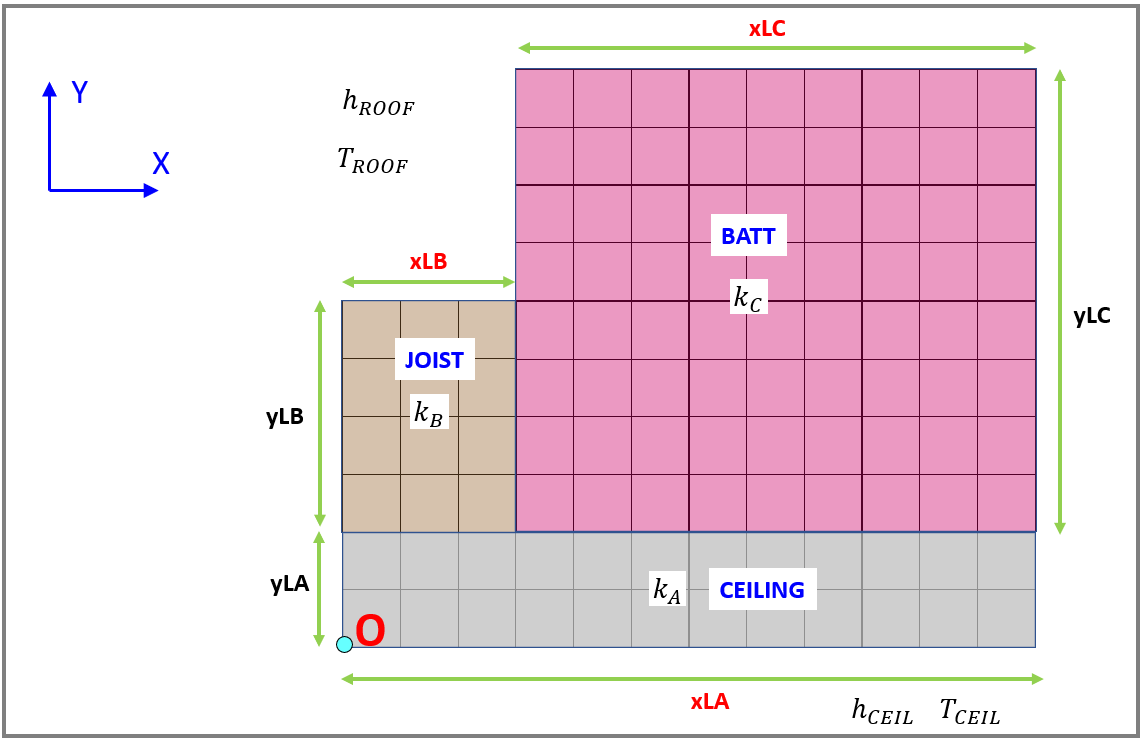

## **Load Thermal and Geometric parameters**

OBJ_params = bh_sys_params_CLS("bh_PARAMS_DATABASE.xlsx", "SET_1")

OBJ_params =   bh_sys_params_CLS with properties:

     Filename: "bh_PARAMS_DATABASE.xlsx"
    Sheetname: "SET_1"
       my_tab: [19×5 table]
          k_A: 0.1700
          k_B: 0.1200
          k_C: 0.0488
       h_ROOF: 4
       h_CEIL: 1.3000
       T_ROOF: 55
       T_CEIL: 25
          xLA: 0.3000
          xLB: 0.0175
          xLC: 0.2825
          yLA: 0.0130
          yLB: 0.0900
          yLC: 0.1950
         Nx_A: []
         Nx_B: []
         Nx_C: []
         Ny_A: []
         Ny_B: []
         Ny_C: []
      Delta_X: []
      Delta_Y: []


## Some system dimensions:

xLb = OBJ_params.xLB;  % (m)
xLc = OBJ_params.xLC;  % (m)

yLa = OBJ_params.yLA;  % (m)
yLb = OBJ_params.yLB;  % (m)
yLc = OBJ_params.yLC;  % (m) 

## **Create a Steady State Thermal model**

thermalmodel = createpde('thermal','steadystate');

## **Define the geometry of our 3 "blocks"**

- $\textrm{R1A}:$ will be our **gypsum** rectangle

- $\textrm{R2B}:$ will be our **joist** rectangle

- $\textrm{R3C}:$ will be our **batt** rectangle

- For a rectangle, the first row contains 3, and the second row contains 4. 

- The next four rows contain the x-coordinates of the starting points of the edges, and the four rows after that contain the y-coordinates of the starting points of the edges.

R1A_gdm_gyp  = [3 4   0      (xLb+xLc)   (xLb+xLc)      0 ...
                     0      0           yLa            yLa]';

R2B_gdm_joi  = [3 4   0       xLb         xLb          0 ...
                     yLa     yLa        (yLa+yLb)    (yLa+yLb)]';

R3C_gdm_bat  = [3 4   xLb    (xLb+xLc)   (xLb+xLc)     xLb  ...
                     yLa     yLa        (yLa+yLc)    (yLa+yLc)]';

We'll use the [`decsg`](matlab:  doc decsg)() function and the [`geometryFromEdges`](matlab:  doc geometryFromEdges)() function

ns  = char('R1', 'R2', 'R3')';
gdm = [R1A_gdm_gyp, R2B_gdm_joi, R3C_gdm_bat];

g   = decsg(gdm,'R1+R2+R3',ns);

geometryFromEdges(thermalmodel,g);

## Visualize the geometry

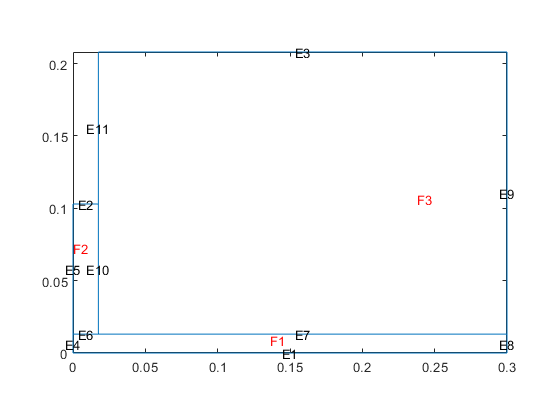

figure;
    pdegplot(thermalmodel,'EdgeLabels','on','SubdomainLabels','on')
        axis equal

## Setup the boundary conditions

- Roof space surface heat transfer coefficients h = 4 W/m2K.

- Indoor space surface heat transfer coefficients h = 1.3 W/m2K

- *Tc* = indoor space temperature (25°C)

- Select roof space temperatures allowing for summer design conditions for Rockhampton which is  (32°C).  

- $\Longrightarrow \;$   ***So .... a Roof space temperature of say 55°C  ?***

% EDGE 1:  boundary with INDOOR living space
thermalBC(thermalmodel,'Edge',1,'ConvectionCoefficient',OBJ_params.h_CEIL, 'AmbientTemperature',OBJ_params.T_CEIL);

% EDGE 2,3,11:  boundary with ROOF cavity space
thermalBC(thermalmodel,'Edge',2, 'ConvectionCoefficient',OBJ_params.h_ROOF, 'AmbientTemperature',OBJ_params.T_ROOF);
thermalBC(thermalmodel,'Edge',3, 'ConvectionCoefficient',OBJ_params.h_ROOF, 'AmbientTemperature',OBJ_params.T_ROOF);
thermalBC(thermalmodel,'Edge',11,'ConvectionCoefficient',OBJ_params.h_ROOF, 'AmbientTemperature',OBJ_params.T_ROOF);

% EDGE 9: is our BATT symmetry BC, ie: dT/dx = 0
thermalBC(thermalmodel,'Edge',9,'HeatFlux',0);
% EDGE 8: is our GYPSUM symmetry BC, ie: dT/dx = 0
thermalBC(thermalmodel,'Edge',8,'HeatFlux',0);

% EDGE 5: is our JOIST symmetry BC, ie: dT/dx = 0
thermalBC(thermalmodel,'Edge',5,'HeatFlux',0);
% EDGE 4: is our GYPSUM symmetry BC, ie: dT/dx = 0
thermalBC(thermalmodel,'Edge',4,'HeatFlux',0);

## Specify the Initial Conditions

NOTE:  this is a steady state analysis ... so the IC is not important

thermalIC(thermalmodel, 0);

## Specify Thermal Properties of the Materials

Specify the thermal conductivity of the material.

-      
$$k\;\;\left\lbrack \frac{W}{m\ldotp K}\right\rbrack$$
   

thermalProperties(thermalmodel, 'Face', 3, 'ThermalConductivity', OBJ_params.k_C); % BATTS
thermalProperties(thermalmodel, 'Face', 2, 'ThermalConductivity', OBJ_params.k_B); % JOISTS
thermalProperties(thermalmodel, 'Face', 1, 'ThermalConductivity', OBJ_params.k_A); % GYPSUM

## Generate the mesh

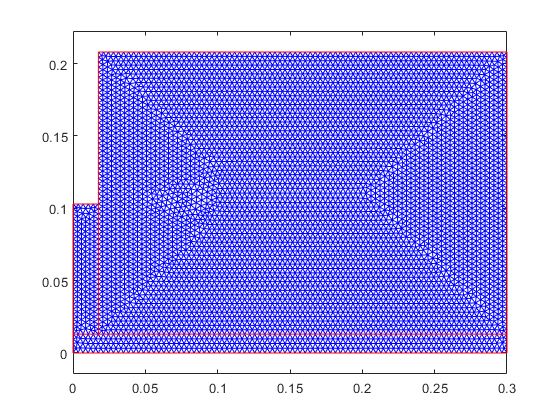

generateMesh(thermalmodel, 'Hmax', xLb/5);

figure
    pdeplot(thermalmodel)

## Calculate Solution

Use the [`solve`](matlab:  web(fullfile(docroot, 'pde/ug/pde.thermalmodel.solve.html'))) function to calculate the solution.

NOTE:  the returned result will be a [`SteadyStateThermalResults`](matlab:  web(fullfile(docroot, 'pde/ug/pde.steadystatethermalresults.html'))) object

thermalresults = solve(thermalmodel)

thermalresults =   SteadyStateThermalResults with properties:

    Temperature: [22993×1 double]
     XGradients: [22993×1 double]
     YGradients: [22993×1 double]
     ZGradients: []
           Mesh: [1×1 FEMesh]


## Visualize the solution:

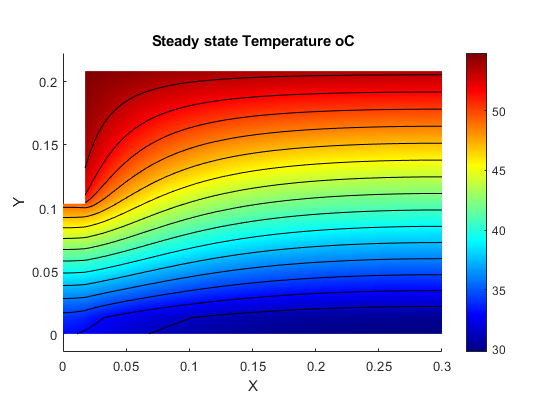

figure;
    pdeplot(thermalmodel,'XYData',thermalresults.Temperature,'ColorMap','jet', ...
        "Contour","on", "Levels", 15);
    %pdeplot(thermalmodel,'XYData',thermalresults.Temperature,'ZData',thermalresults.Temperature,'ColorMap','jet');
        xlabel('X');
        ylabel('Y');
        title('Steady state Temperature oC')

I's also like to see the temperature at the ceiling/air interface:

x_list = linspace(0, (xLb + xLc), 200);
y_list = zeros(size(x_list));
Tintrp = interpolateTemperature(thermalresults, x_list, y_list);

mean_T = mean(Tintrp)

mean_T = 30.6723

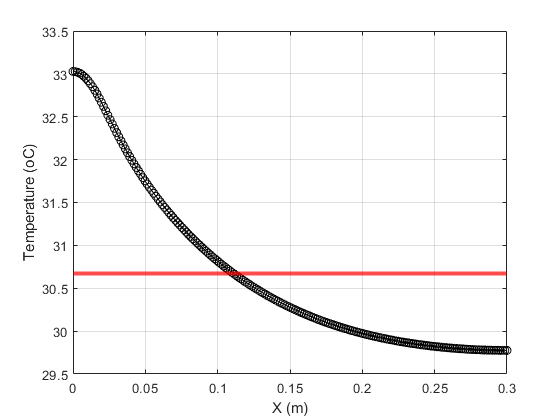


figure;
    plot(x_list, Tintrp, '-ko');
        xlabel('X (m)');
        ylabel('Temperature (oC)');
        grid('on')
    hold('on')
    yline(mean_T, '-r', 'LineWidth',3)

## Now compute the Heat flowing through the ceiling boundary

Qn = evaluateHeatRate(thermalresults,'Edge',1)  

Qn = 2.2108

## Now compute the R value

- R = (Tc – Ta)/Q * A

- where A = ceiling area, *T**a* = air temperature at the roof space and *T**c* = indoor space temperature (25°C)

my_A = (xLc + xLb) * 10;

R = (OBJ_params.T_CEIL - OBJ_params.T_ROOF) / (Qn * my_A) 

R = -4.5233